# Understanding the concept of nyquist criterion

say you have a transfer function L(s) as defines below

L = tf([1,2,3,4],[5,5,7,7,2])

L =
 
       s^3 + 2 s^2 + 3 s + 4
  -------------------------------
  5 s^4 + 5 s^3 + 7 s^2 + 7 s + 2
 
Continuous-time transfer function.
Model Properties


### Seeing the poles and zeros of L(s), L(s)+1

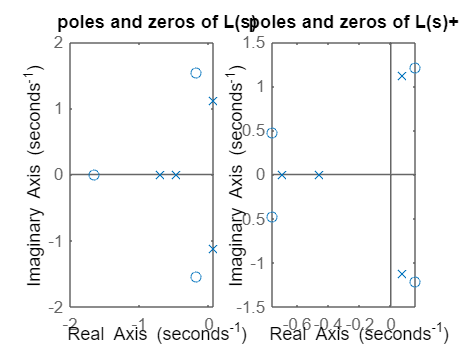

clf
subplot(1,2,1)
pzmap(L)
title('poles and zeros of L(s)')
subplot(1,2,2)
pzmap(L+1)
title('poles and zeros of L(s)+1')

### Nyquist plot of L(s) : plot of L(s) for changing w

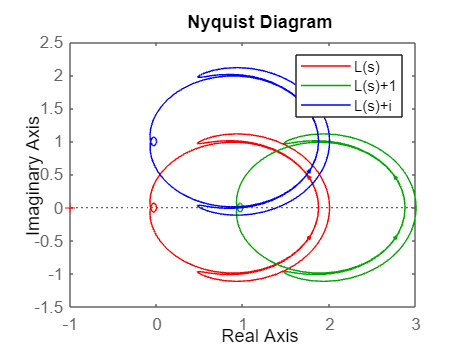

clf
nyquist(L,'r',1+L,'g',1j+L,'b')
legend('L(s)','L(s)+1','L(s)+i')

## Conclusion

open loop Tf = L(s)

Closed loop TF = L(s)/(1+L(s))

we plotted L(s), L(s)+1 nyquist plots

We conclude that we may get some info on closed loop poles form Nyquist plot of open loop TF.

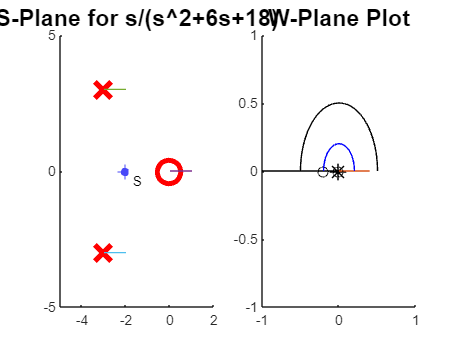

Interact

## Nyquist criteria

We now understood that circling around zeros would give us circling around origin.

s -----------> L(s)

Hence now we try to circle around total RHP plane, Lets see why do we do this

- If we had any net zeros, for example 4 zeros, 3 poles of L(s) lie in RHP, then 1 clockwise encirclement around origin.

- Now we understand how many poles or zeros of L(s) are there in RHP.

- But we need 1+L(s) zeros which are the poles of closed loop system.

- We know the nyquist plot of 1+L(s) is plot 1 shifted towards right.

- Instead of plotting mapping from    s------------> 1+L(s) for encirclement around origin we directly check encirclement around -1 point in L(s) nyquist plot. Because both are same.

- Hence we see the encirclements around -1 point in L(s) plot.

### Finding whether the closed loop system contains RHP poles or not

- RHP Poles of closed loop system means RHP zeros of 1+L(s).

- We get the 1+L(s) RHP zeros from the previous methos (relative no of zeros and poles)

- EX: lets say we got 1 clockwise encirclement around -1, that means there is definitely a RHP zero for 1+L(s) == RHP pole of closed loop system.

- EX: lets say we got 1 counter clockwise encirclement around -1, that means we cant tell number of zeros but we can say that if there are '**N**' zeros then there are **Z+1 **poles. But we know that poles of L(s) = poles of 1+L(s). Hence we know how many poles are there in 1+L(s) from L(s).

Now if L(s) has 1 pole then number of zeros in 1+L(s) = Z = 0.

### Formula:

Z = P-N

Z = RHP zeros of 1+L(s)

P = RHP poles of 1+L(s)

N = anticlockwise encirclements around -1 point

Ex: say we have 4 poles but only 3 encirclements, then it means there is 1 zero which is cancelling the phase of one pole.